x1=[-12 28 8];
x2=[-3 -23 27];
d(1)=det([28 8;-23 27]);
d(2)=-det([-12 8;-3 27]);
d(3)=det([-12 28;-3 -23]);
d=d/100;
% d=cross(x1,x2)

% dot(x, y)内积和cross(x, y)外积

[x,y]=meshgrid(-10:1:10);
z= -1/d(3)*(d(1)*x+d(2)*y);
figure(1);
surf(x,y,z);
hold on
v=[0 0 0;d;]

v =          0         0         0
    9.4000    3.0000    3.6000


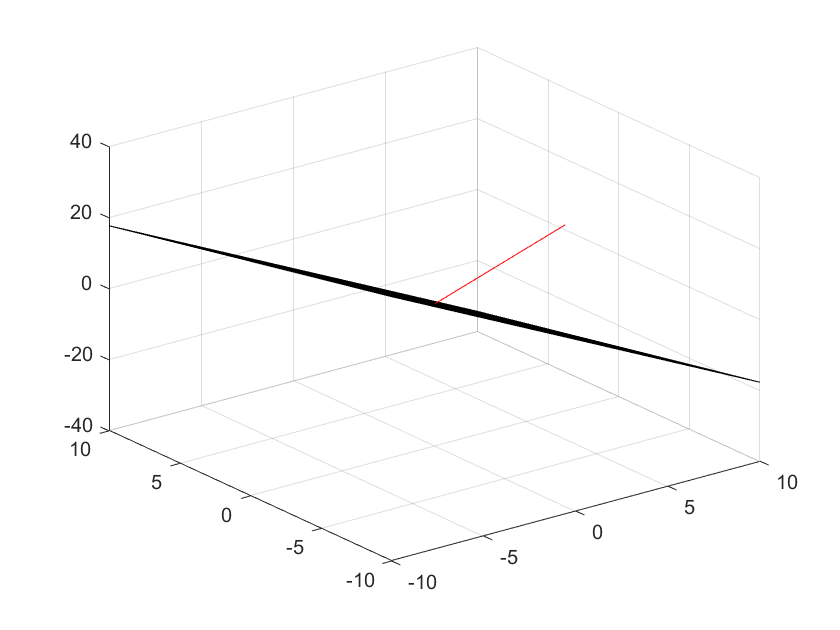

plot3(v(:,1),v(:,2),v(:,3),'r');
hold off

% help patch - 创建一个或多个填充多边形

%y = pinv(A)*b
A = [x1;x2];
sym(A)

$$ans = \left(\begin{array}{ccc} -12 & 28 & 8\\ -3 & -23 & 27 \end{array}\right)$$

rref([A,[0;0;]])%rrefmovie(A) 

ans =     1.0000         0   -2.6111         0
         0    1.0000   -0.8333         0


%Z = null(A) 是从奇异值分解获得的 A 的零空间的正交基.
%Z = null(A,'r') 是从简化行阶梯形矩阵获得的零空间的“有理”基.
null(A,"r")

ans =     2.6111
    0.8333
    1.0000


%http://www.doc88.com/p-6731713601034.html 矩阵练习
%https://max.book118.com/html/2019/0730/8023026123002037.shtm 矩阵分解